% 26 - septiembre - 2023
% Valeria Castañon
% practica 4

1.- Ejecuta el comando load('handel.mat')

load('handel.mat');

2.- Abrir uno de los archivos para verificar que se trata de datos numéricos.

%disp(y);

3.- Cargar los datos del sonido digitalizado (archivo de texto) al ‘Workspace’ de MATLAB. Usar la función load y guardar en una variable con el mismo nombre.

y = y;

4.- Después de hacer esto deben aparecerlas variables en el Workspace.

%disp(y);

5.- Generar el vector ‘np’, ‘nd’, ‘nde’, ‘ns’ correspondiente al tiempo de las variables. Debentener el mismonúmero de elementos que los que tiene  la variable.

% generar vectores np,nd,nde y ns
tamanio = (round(length(y)/4));  % dividiir la muestra  en 4 espacios
v1 = y(1);
np = [v1];

v2 = y(tamanio);
nd = [v2];

v3 = y(tamanio*2);
nde = [v3];

v4 = y(tamanio*3);
ns = [v4];

for i=2:tamanio
    np = [np,y(i)];
end

for i=tamanio+1:tamanio*2
    nd = [nd,y(i)];
end

for i=tamanio*2+1:tamanio*3
    nde = [nde,y(i)];
end

for i=tamanio*3+1:tamanio*4+1
    ns = [ns,y(i)];
end

6.- Graficar cada una de las señales usando la función stem, recuerda que debe graficarse y contra np.

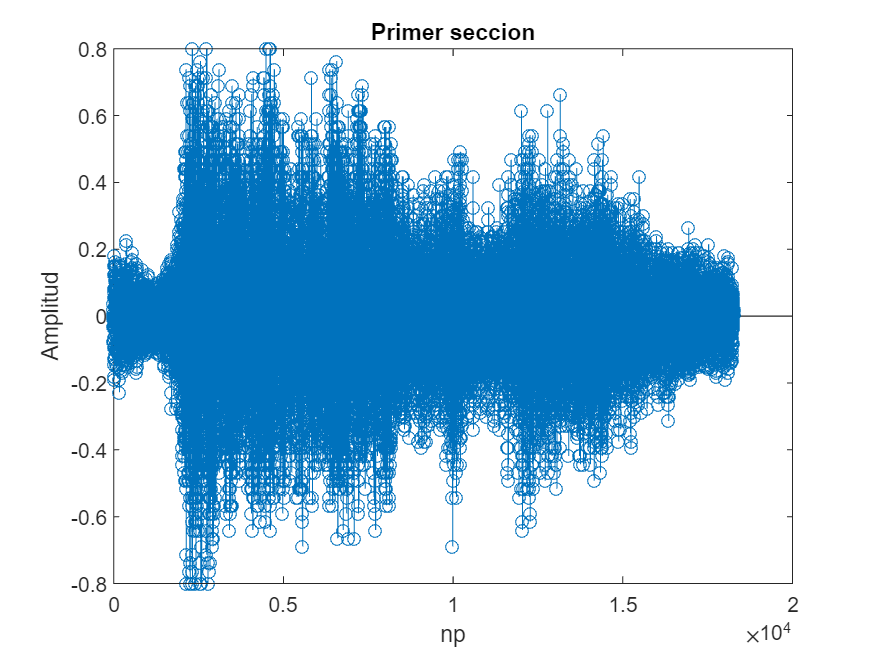

stem(np);
title("Primer seccion");
xlabel("np");
ylabel("Amplitud");


% stem(nd);
% title("Segunda seccion");
% xlabel("nd");
% ylabel("Amplitud");
% stem(nde);
% title("Tercera seccion");
% xlabel("nde");
% ylabel("Amplitud");
% stem(ns);
% title("Cuarta seccion");
% xlabel("ns");
% ylabel("Amplitud");

7.- Reproducir las señales como sonido a una frecuencia de muestreo de 8000 hz utilizando la función de MATLAB que te permita realizar este proceso. Observe las diferencias de sonido y gráfico para cada uno de los anteriores incisos dando una explicación de la diferencia. 

Fs es la frecuencia de muestreo y debes desarrollarlo para los siguientes valores de Fs:

- 4000

% sound(nd,4000);

[P,Q] = rat(4000/Fs);
abs(P/Q*Fs-4000);
xnew = resample(nd,P,Q);

stem(xnew);
xlim([0, 2*10^4]); % Fijar el rango en el eje x
ylim([0, 1]); % Fijar el rango en el eje y
title("Señal: 4000Hz");
xlabel("nd");
ylabel("Amplitud");

- 5000

% sound(nd,5000);
% 
% [P,Q] = rat(5000/Fs);
% abs(P/Q*Fs-5000);
% xnew = resample(nd,P,Q);
% 
% stem(xnew);
% title("Señal: 5000Hz");
% xlabel("nd");
% ylabel("Amplitud");

- 8000

% sound(nd,8000);
% 
% [P,Q] = rat(8000/Fs);
% abs(P/Q*Fs-8000);
% xnew = resample(nd,P,Q);
% 
% stem(xnew);
% title("Señal: 8000Hz");
% xlabel("nd");
% ylabel("Amplitud");

- 20000

% sound(nd,20000);
% 
% [P,Q] = rat(20000/Fs);
% abs(P/Q*Fs-20000);
% xnew = resample(nd,P,Q);
% 
% stem(xnew);
% title("Señal: 20000Hz");
% xlabel("nd");
% ylabel("Amplitud");

8.- Obtener la suma de las cuatro señales y guardarla en una variable con nombre sumaSenal.

nd(end) = [];
nde(end) = [];
ns(end-1:end) = [];
sumaSenal = np+(nd)+(nde)+ns;

9.- Graficar la señal sumaSenal y reproducirla como sonido.

% stem(sumaSenal);
% title("Suma señal");
% xlabel("np");
% ylabel("Amplitud");

% sound(sumaSenal,Fs);

10.- Realizar las operaciones necesarias para concatenar las cuatro señales en el mismo orden que en (1) dándoles un espaciamiento de 2000 muestras y  guardarlas en la señal datosConcatenados. Graficar y reproducir.

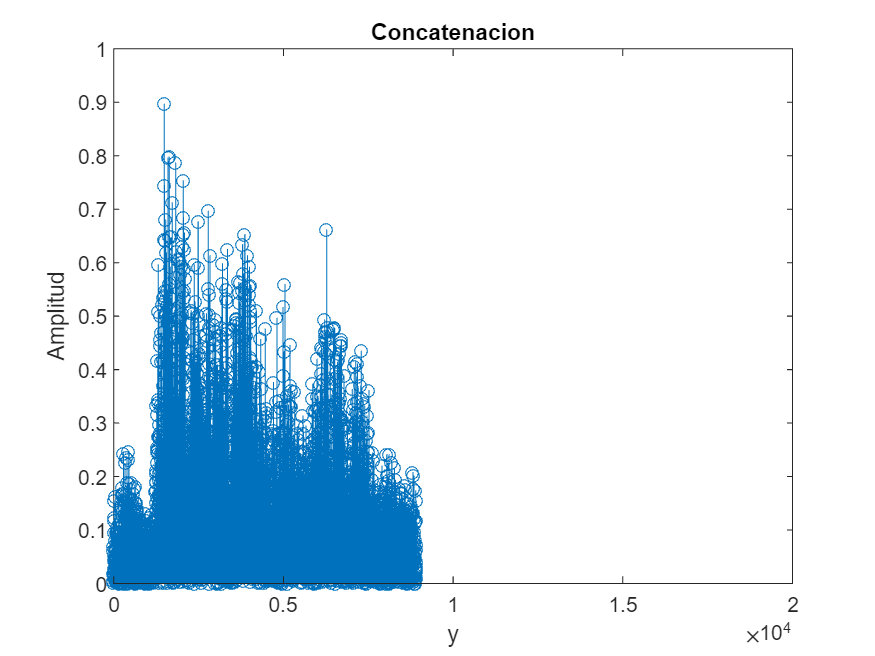

espaciado = zeros(1, 2000);
datosConcatenados = [np,espaciado,nd,espaciado,nde,espaciado,ns];

% stem(datosConcatenados);
title("Concatenacion");
xlabel("y");
ylabel("Amplitud");


sound(datosConcatenados,Fs);

11.- Invertir la señal datosConcatenados y guardalos en invertida.

invertida = fliplr(datosConcatenados);

12.- Graficar y reproducir la señal invertida.

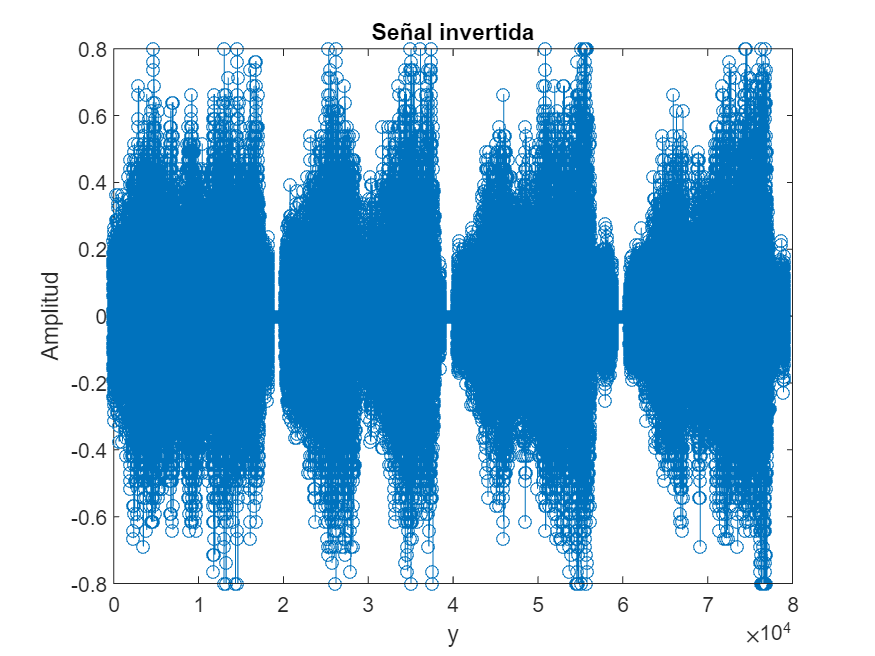

stem(invertida);
title("Señal invertida");
xlabel("y");
ylabel("Amplitud");


sound(invertida,Fs);